clear

A1=readtable("MatLab cinetica\Reacciones actuador central\A1.txt","Delimiter"," ");

A1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A2=readtable("MatLab cinetica\Reacciones actuador central\A2.txt","Delimiter"," ");

A2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A3=readtable("MatLab cinetica\Reacciones actuador central\A3.txt","Delimiter"," ");

A3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B1=readtable("MatLab cinetica\Reacciones actuador central\B1.txt","Delimiter"," ");

B1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B2=readtable("MatLab cinetica\Reacciones actuador central\B2.txt","Delimiter"," ");

B2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B3=readtable("MatLab cinetica\Reacciones actuador central\B3.txt","Delimiter"," ");

B3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C1=readtable("MatLab cinetica\Reacciones actuador central\C1.txt","Delimiter"," ");

C1.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C2=readtable("MatLab cinetica\Reacciones actuador central\C2.txt","Delimiter"," ");

C2.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C3=readtable("MatLab cinetica\Reacciones actuador central\C3.txt","Delimiter"," ");

C3.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];



CargaAxialA1=A1.Fz;
CargaAxialA2=A2.Fz;
CargaAxialA3=A3.Fz;

CargaAxialB1=B1.Fz;
CargaAxialB2=B2.Fz;
CargaAxialB3=B3.Fz;

CargaAxialC1=C1.Fz;
CargaAxialC2=C2.Fz;
CargaAxialC3=C3.Fz;


CargaCortanteA1=sqrt(A1.Fx.^2+A1.Fy.^2);
CargaCortanteA2=sqrt(A2.Fx.^2+A2.Fy.^2);
CargaCortanteA3=sqrt(A3.Fx.^2+A3.Fy.^2);
CargaCortanteB1=sqrt(B1.Fx.^2+B1.Fy.^2);
CargaCortanteB2=sqrt(B2.Fx.^2+B2.Fy.^2);
CargaCortanteB3=sqrt(B3.Fx.^2+B3.Fy.^2);
CargaCortanteC1=sqrt(C1.Fx.^2+C1.Fy.^2);
CargaCortanteC2=sqrt(C2.Fx.^2+C2.Fy.^2);
CargaCortanteC3=sqrt(C3.Fx.^2+C3.Fy.^2);



Altura=82.55/1000

Altura = 0.0826

Diametro=25.4*1.5/1000

Diametro = 0.0381

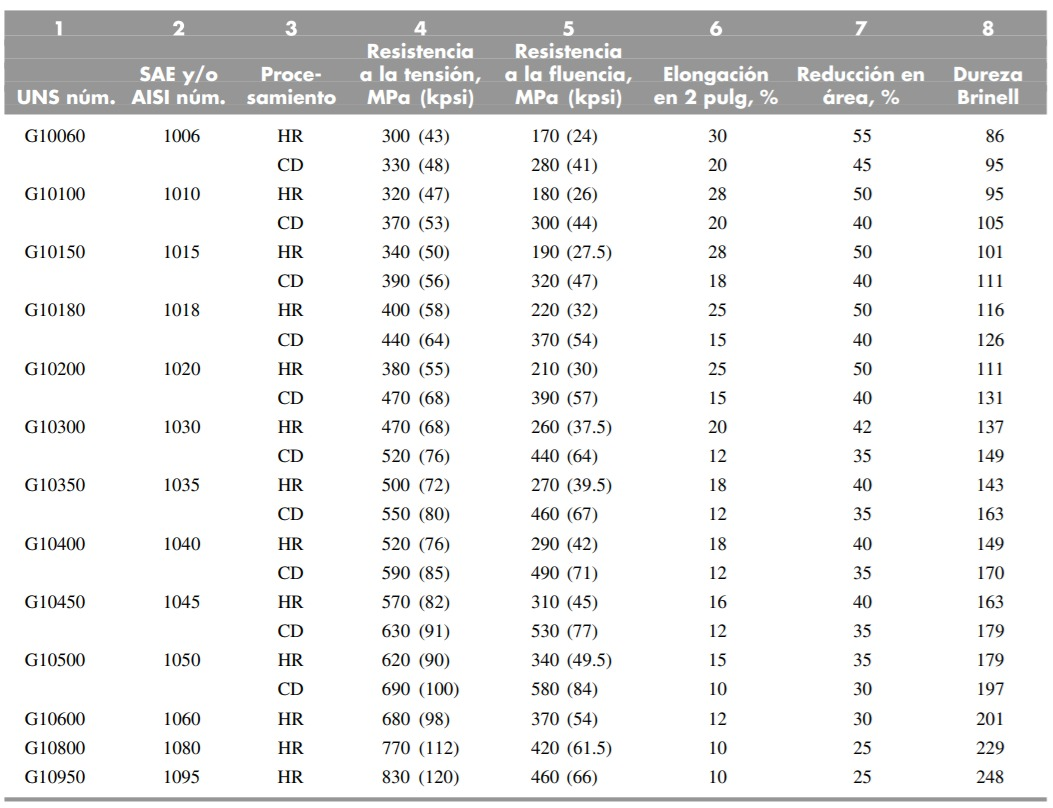


Sut=630  

Sut = 630

Sy=530

Sy = 530

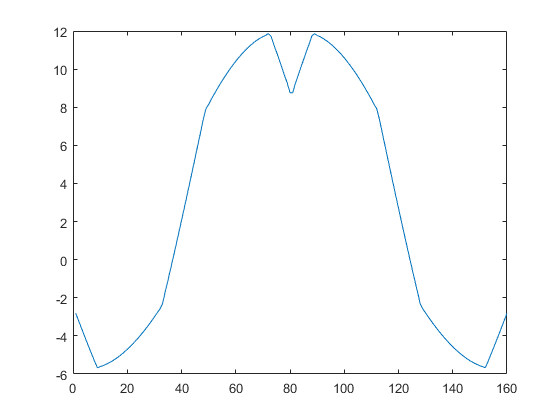


kt=2;
neuberF=0.07; %Corregir neuber
neuberT=0.055;
radioMuesca=0.1; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1);
KfsmSold=1+qTorsion*(kt-1);


I=pi*Diametro^4/64;
J=pi*Diametro^4/32;
A=pi*Diametro^2/4;
MT=CargaCortanteC3*Altura;


%plot(B3.Mz/1000)
%plot(A3.Mz/1000)
%plot(C3.Mz/1000)





Sigma_t=MT*0.5*Diametro/I;
Sigma_c=-MT*0.5*Diametro/I;
Sigma_normal=CargaAxialC3/A;

plot(Sigma_normal/1000000)

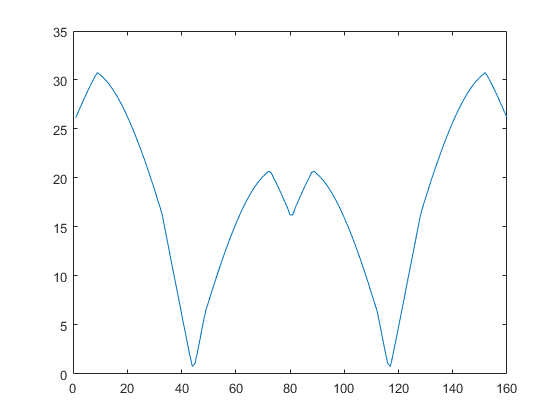

plot(Sigma_t/1000000)




Sigma_t_Total=KfSold*(Sigma_normal+Sigma_t)

Sigma_t_Total = 	1.0e+07 *

    4.2458
    4.2935
    4.3407
    4.3864
    4.4300
    4.4705
    4.5067
    4.5384
    4.5617
    4.5315


Sigma_c_Total=KfSold*(Sigma_normal+Sigma_c)

Sigma_c_Total = 	1.0e+07 *

   -5.2673
   -5.4501
   -5.6318
   -5.8114
   -5.9874
   -6.1588
   -6.3233
   -6.4821
   -6.6237
   -6.5741



Tau=KfsmSold*C3.Mz/1000*Diametro/(2*J)

Tau = 	1.0e+07 *

    4.5441
    4.8458
    5.1462
    5.4440
    5.7373
    6.0243
    6.3015
    6.5706
    6.8123
    6.7434


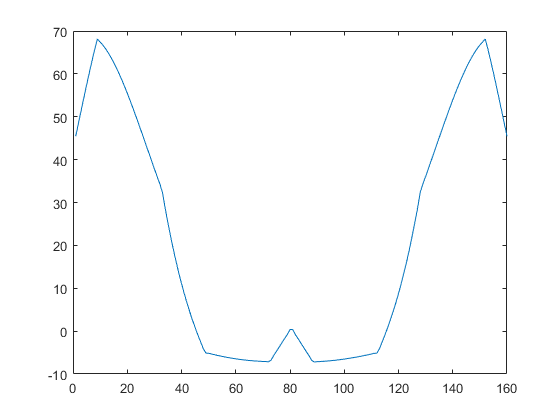

plot(Tau/1000000)

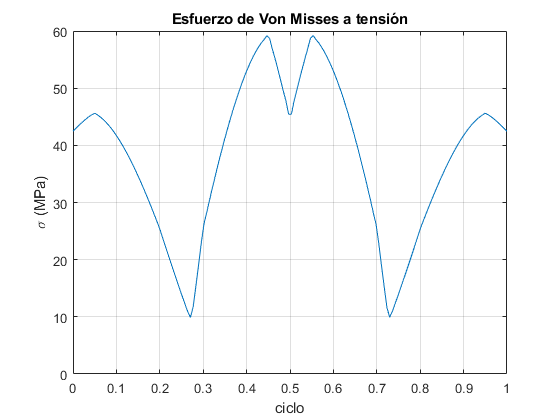




plot(linspace(0,1,160),Sigma_t_Total/1000000)
grid on
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses a tensión")

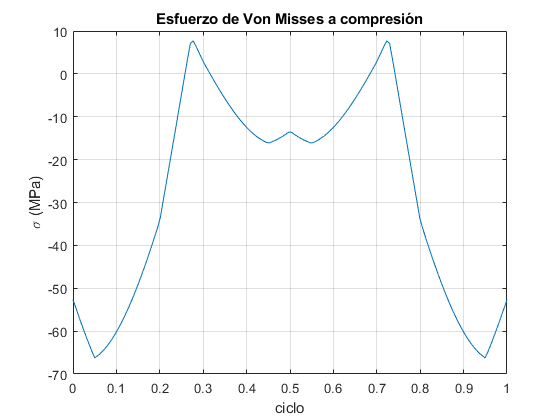

plot(linspace(0,1,160),Sigma_c_Total/1000000)
grid on
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses a compresión")

### Fatiga

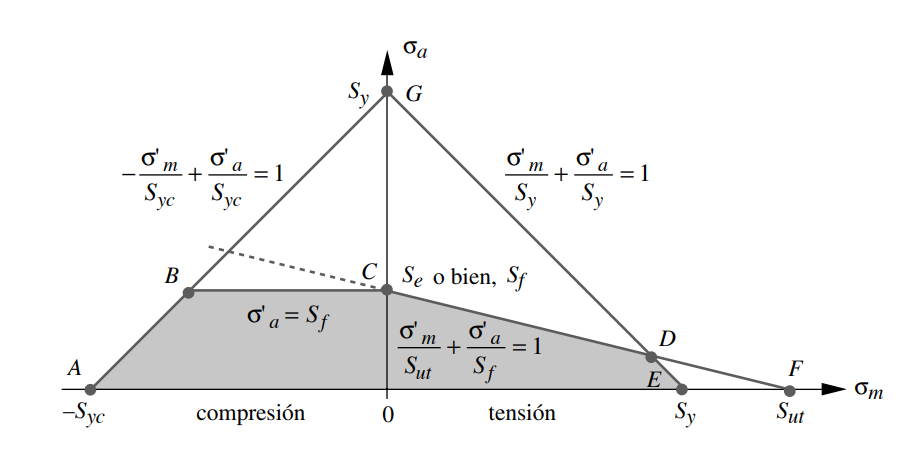

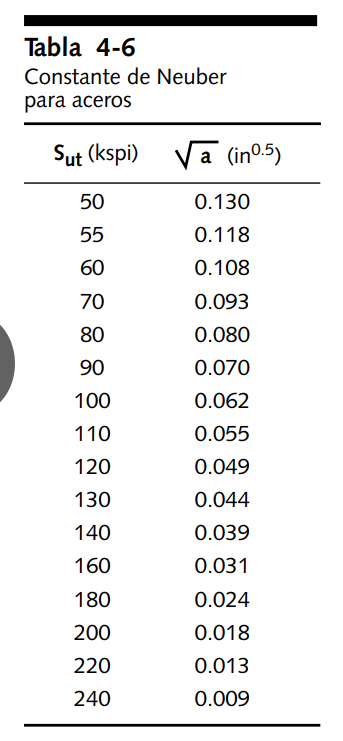


mega=1000000;

TauA=0.5.*abs(max(Tau)-min(Tau))/mega   %esfuerzo alternante

TauA = 37.6769

TauM=0.5.*abs(max(Tau)+min(Tau))/mega 

TauM = 30.4496


sigmaAc=0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega;   %esfuerzo alternante
sigmaMc=0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega;   %esfuerzo medio

sigmaAt=0.5.*abs(max(Sigma_t_Total)-min(Sigma_t_Total))/mega;   %esfuerzo alternante
sigmaMt=0.5.*abs(max(Sigma_t_Total)+min(Sigma_t_Total))/mega;

VMAc=sqrt(0.5*(sigmaAc^2+6*TauA^2))

VMAc = 70.3029

VMMc=sqrt(0.5*(sigmaMc^2+6*TauM^2))

VMMc = 56.6519



VMAt=sqrt(0.5*(sigmaAt^2+6*TauA^2))

VMAt = 67.5456

VMMt=sqrt(0.5*(sigmaMt^2+6*TauM^2))

VMMt = 58.1253

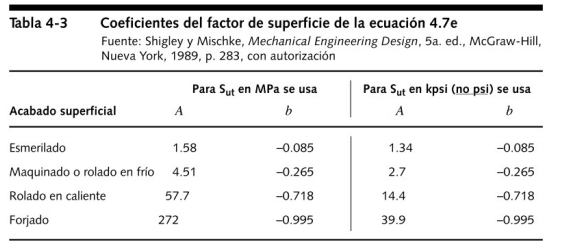

#### Factores de corrección

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;

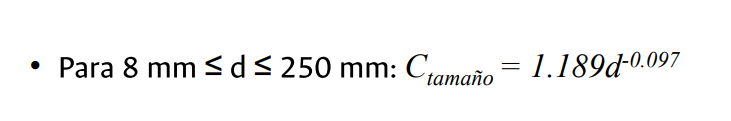

Ctam=1.189*(Diametro*1000)^(-0.097);
Ccon=0.814; % 99%
if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end

Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon;


#### Diagrama de Goodman modificado

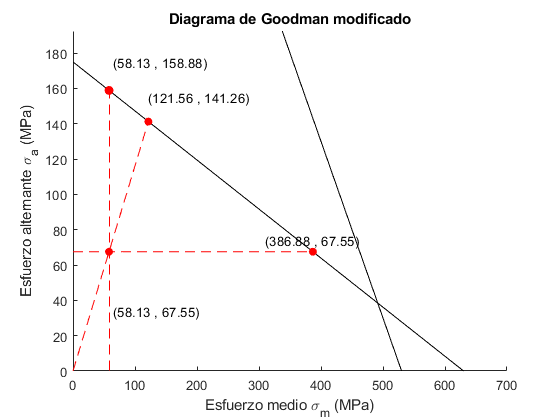

FS1 = 2.3522

FS2 = 2.0913

FS3 = 6.6560

FS_union_biela_t = 2.0913

FS_union_biela_t=diagramaGoodman(VMAt,VMMt,Sut,Sy,Se,true)

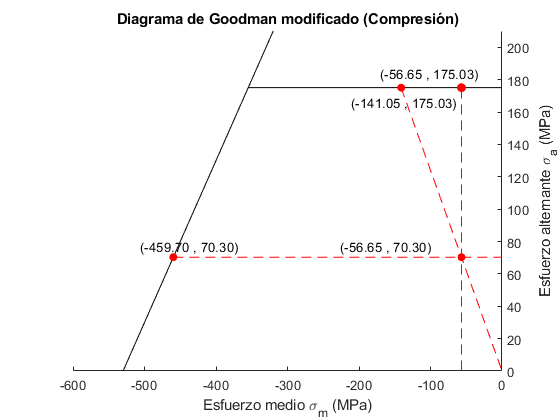

FS1 = 2.4897

FS2 = 2.4897

FS3 = 8.1144

FS_union_biela_c = 2.4897


FS_union_biela_c=diagramaGoodman(VMAc,VMMc,Sut,Sy,Se,false)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end




figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(4*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(3*sigmaM,1.05*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,0.95*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end